# Estimating Sunrise and Sunset

We can estimate the time of sunrise and sunset for any location on the earth if we know the latitude, and longitude for that location.  To estimate sunrise and sunset for any day of the year we need to calculate two values for a given date and place -- the equation of time and the hour angle.

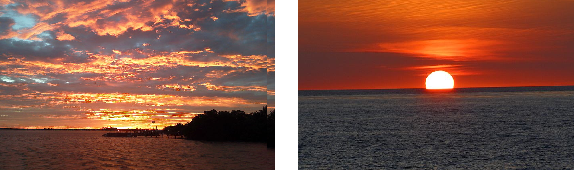

## Set Location and Date Information

For this example, we will use Boston as our location.  Change latitude and longitude using the sliders below.  Use the checkbox to ignore Daylight Saving Time at your location.

lat = 31.3;
lon =-80.8;
useStandardTime = false;

today = datetime(2020,10,01,00,00,00,"TimeZone","UTC");
yearStart = dateshift(today,"start","year");               % midnight beginning of year
yearEnd = dateshift(today,"end","year");          % midnight end of year
date = (yearStart+hours(12)):caldays(1):yearEnd;           % noon on each day of year

## Calculate the Equation of Time

The [Equation of Time](https://en.wikipedia.org/wiki/Equation_of_time) is the difference between two types of solar time -- the *apparent solar time* which directly tracks the motion of the sun and a theoretical *mean solar time.*  The discrepancy is related to the eccentricity of the earth's orbit.

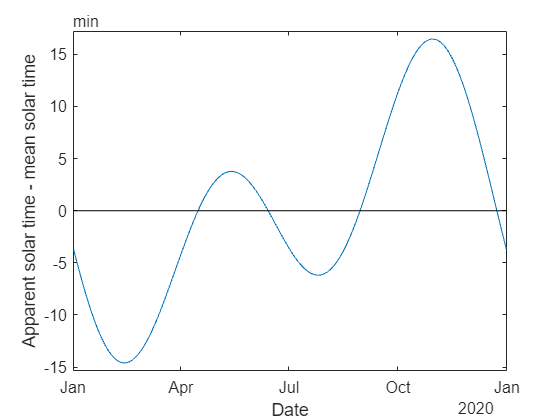

B = 360*(day(date,'dayofyear')-81)/365;
eot = minutes(9.87*sind(2*B) - 7.53*cosd(B) - 1.5*sind(B));
plot(date,eot)
xlabel('Date')
ylabel('Apparent solar time - mean solar time')
line(date,minutes(zeros(size(date))),'Color','k');

## Calculate the Hour Angle

Using the latitude ($\phi$) and an approximation to the sun's declination ($\delta$), approximate the sun's hour angle  ($\omega$) at noon each day of the year at that location.

 
$$\omega \cong {\pm \cos }^{-1} \left(\frac{\cos \left(90\ldotp 833\right)}{\cos \left(\phi \right)\cos \left(\delta \right)}-\tan \left(\phi \right)\tan \left(\delta \right)\right)$$


yearFrac = (date - yearStart) ./ (yearEnd - yearStart);    % year fraction at noon each day
gamma = 2*pi * yearFrac;                                   % year fraction in radians
delta = 0.006918 - 0.399912*cos(gamma) + 0.070257*sin(gamma) - 0.006758*cos(2*gamma) ...
    + 0.000907*sin(2*gamma) - 0.002697*cos(3*gamma) + 0.00148*sin(3*gamma);
omega = acosd((cosd(90.833)./(cosd(lat).*cos(delta))) - tand(lat).*tan(delta));

## Estimate Sunrise and Sunset Times

With the equation of time and the hour angle, we can estimate sunrise and sunset times  in the UTC time zone.


$$\mathrm{sunrise}=\text{12:00}-4*\left(\lambda +\omega \right)-\Delta_{\mathrm{EoT}} \qquad\mathrm{sunset}=\text{12:00}-4*\left(\lambda -\omega \right)-\Delta_{\mathrm{EoT}}$$


sunrise2020 = date - minutes(4*(lon + omega)) - eot;
sunset2020  = date - minutes(4*(lon - omega)) - eot;

To calculate sunrise and sunset in local time, we must find the time zone that corresponds to the specified latitude and longitude, and adjust the times to that  time zone and to account for Daylight Saving Time.

tz = locationToTimeZone(lat,lon,"UTC")

tz = "Etc/GMT+5"

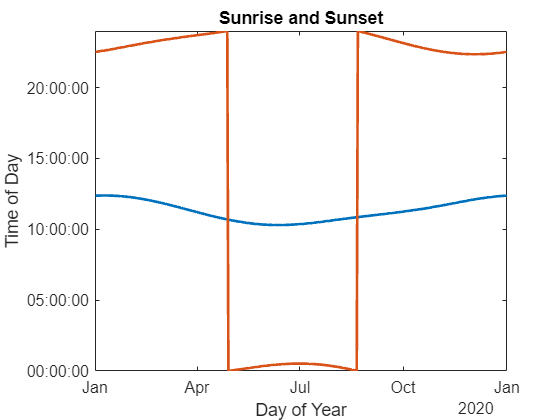



figure()
plot(date,timeofday(sunrise2020),date,timeofday(sunset2020), "LineWidth",2);
title("Sunrise and Sunset")
xlabel("Day of Year"); ylabel("Time of Day")
ylim(hours([0 24]));

## Acknowledgements

These calculations are based on simple approximations available from [NOAA's Earth System Research Laboratory](https://www.esrl.noaa.gov/gmd/grad/solcalc/solareqns.PDF); much more accurate calculations are possible.

With regard to the data for calculating timezone from location, that data is from [http://efele.net/maps/tz/world/.](http://efele.net/maps/tz/world)  The data is derived from VMAP0 data developed by the United States National Imagery and Mapping Agency and are reproduced with permission.  This product has neither been endorsed nor authorized by the United States National Imagery and Mapping Agency or the United States Department of Defense.

function tz = locationToTimeZone(lat,lon,useStandardTime)
load timeZones.mat timeZones

lat = single(lat);
lon = single(lon);
for i = 1:size(timeZones,1)
    if inpolygon(lon, lat, timeZones(i).Lon,timeZones(i).Lat)
        if useStandardTime
            tz = timeZones(i).FixedID;
        else
            tz = timeZones(i).ID;
        end
        return
    end
end

tz = compose("Etc/GMT%+d",-floor((lon+7.5)/15)); % opposite sign conventions

end